# Create Function Plots

`fplot` plots a curve defined by the function $y=f\left(x\right)$ for either a defined interval or an unbounded domain.

## Define a Function 

Create an anonymous function handle for the function $y=\sin \left(x\right)$

fun = @(x) sin(x);

## Plot a Basic Function

Pass the function to `fplot` to generate a plot over the default interval of $\left\lbrack -5,\;5\right\rbrack$

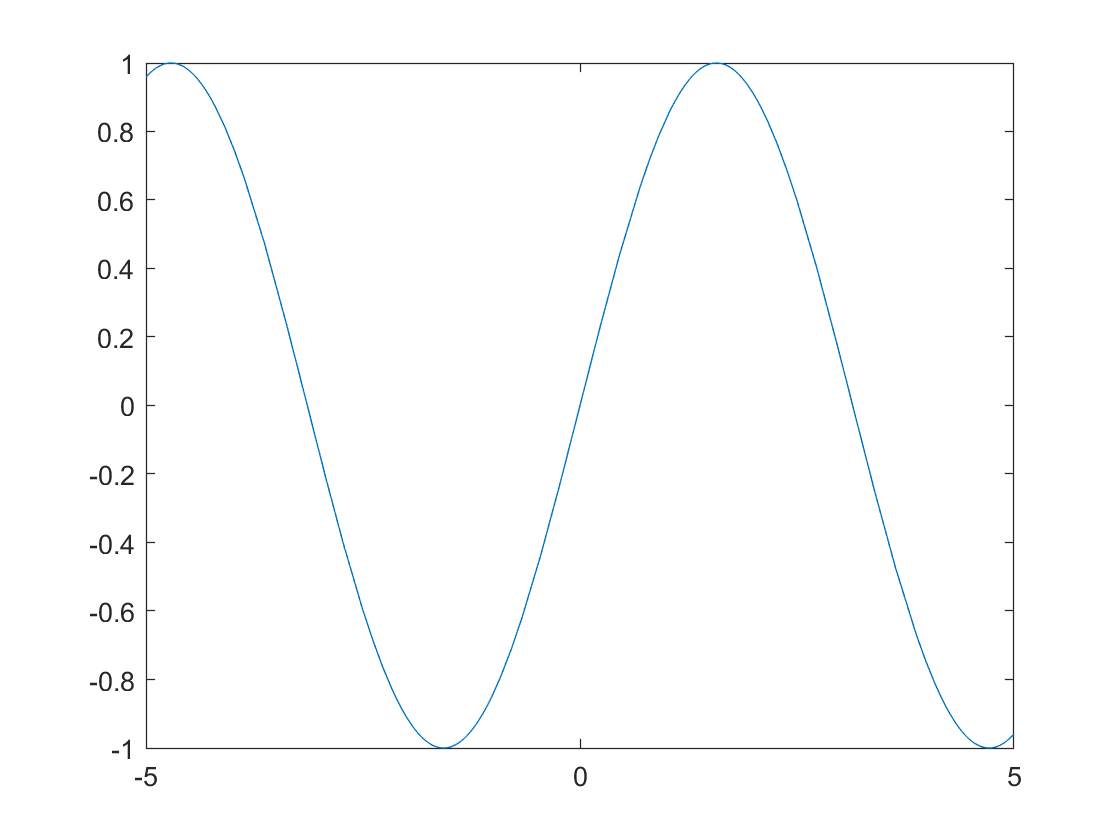

fplot(@(x) sin(x))

## Customizations

### Specify Line Properties 

Plot three sine waves with different phases. For the first, use a line width of 2 points. For the second, specify a dashed red line style with circle markers. For the third, specify a cyan, dash-dotted line style with asterisk markers.

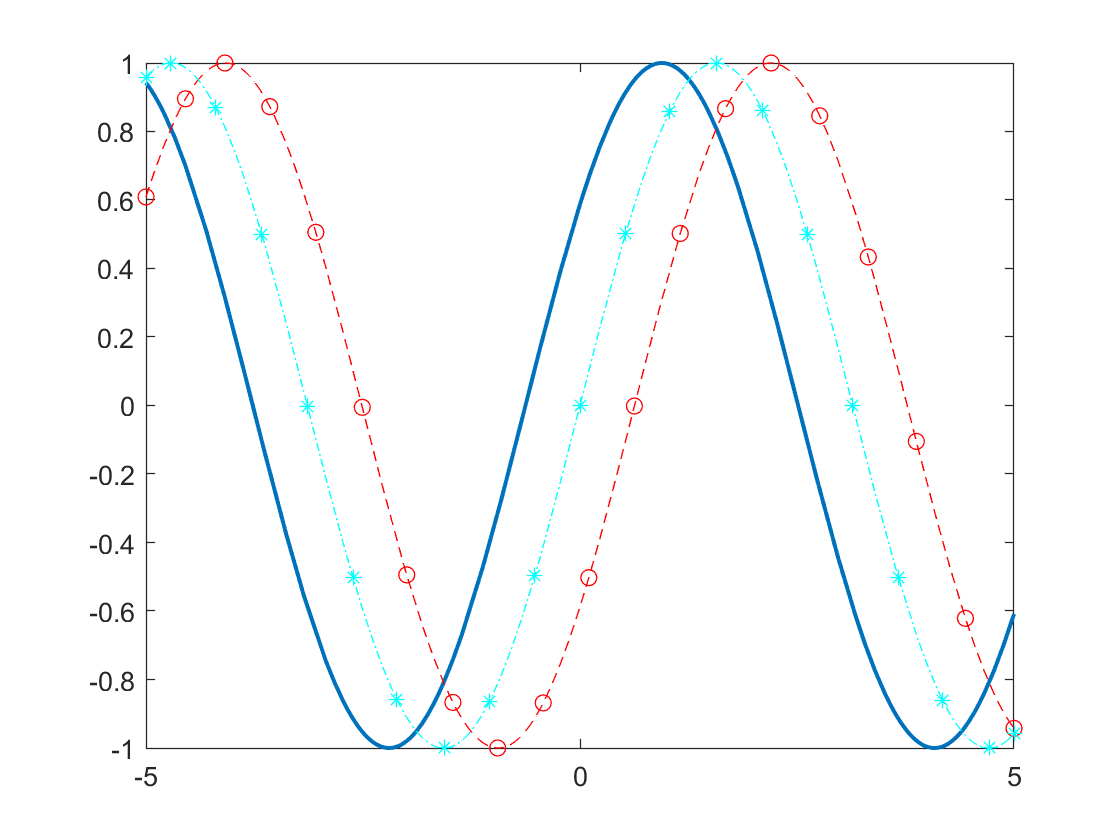

LineWidth = 1.5;
fplot(@(x) sin(x+pi/5),...
    "Linewidth",LineWidth);                 % Specify the line thickness
hold on
fplot(@(x) sin(x-pi/5),'--or');             % Specify line options
fplot(@(x) sin(x),'-.*c')                   % Specify line options
hold off

### Plot Parametric Functions

Providing fplot with two functions, such as $x=\cos \left(3t\right)$ and $y=\sin \left(2t\right)$, will parametrically plot the curves of $x$ and $y$.

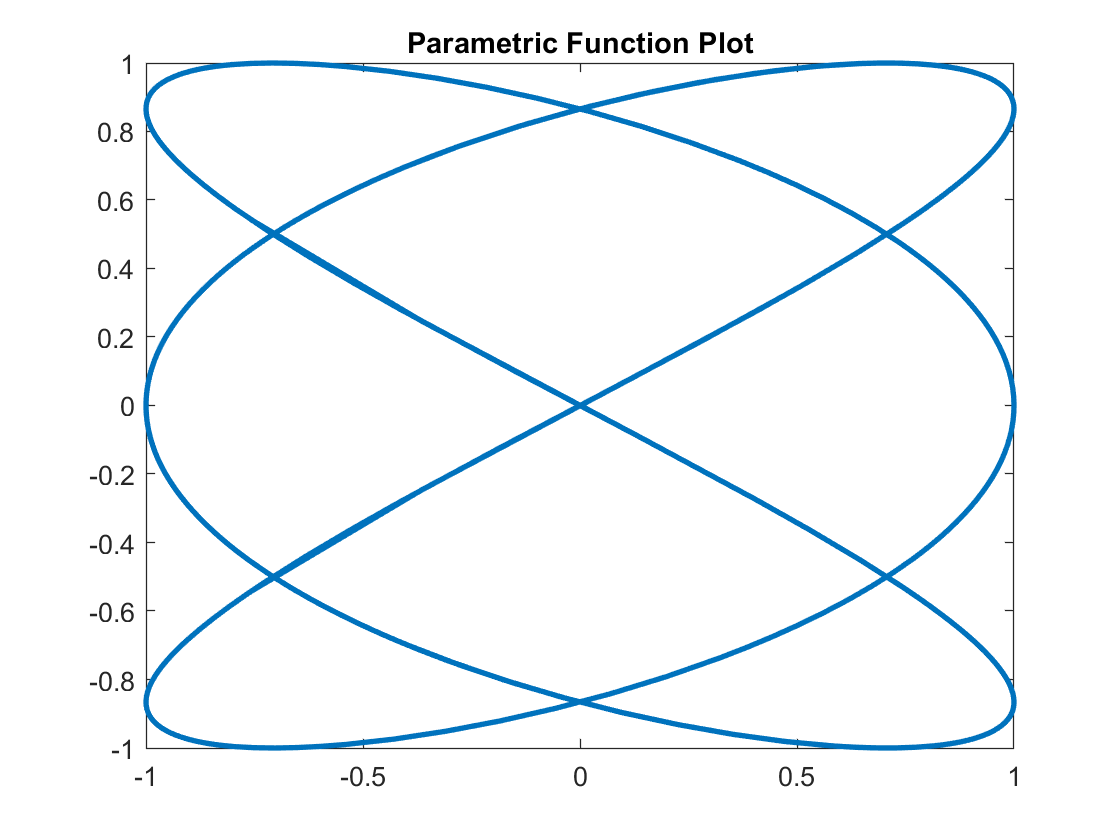

xt = @(t) cos(3*t);
yt = @(t) sin(2*t);
fp = fplot(xt,yt,...
    "LineWidth",2);          % Set the line width to 2

title("Parametric Function Plot")

## Additional Information

### Get All Fplot Properties

Graphics objects in MATLAB have many properties. To see all the properties of a fplot, uncomment the following code

% get(fp)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[fplot](https://www.mathworks.com/help/matlab/ref/fplot.html)